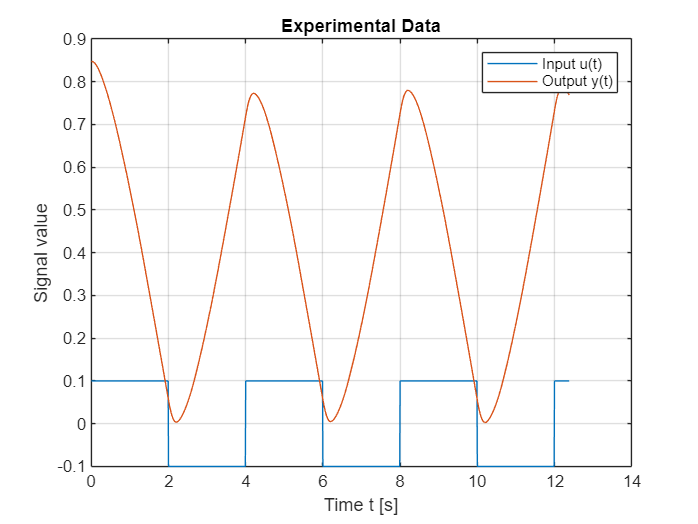

%% Cart Parameter Identification Using Experimental Data
% System identification of a cart (without pendulum)
% Input signal: square wave
% Method: Nonlinear least-squares optimization (fminsearch)
% Model: x" + ax' = bu

clear; clc; close all;

%% Load measurement data
load('cart_inertia.mat');

t = cart.time;                 % Time vector
u = cart.signals(1).values;    % Input (square wave)
y = cart.signals(2).values;    % Measured output (position)

%% Plot measurement data
figure;
plot(t, u, t, y);
legend('Input u(t)', 'Output y(t)');
xlabel('Time t [s]');
ylabel('Signal value');
title('Experimental Data');
grid on;


%% Parameter estimation using nonlinear optimization
x0 = [1, 1];   % Initial guess for parameters [a, b]

x_opt = fminsearch(@(x) costFunction(x, t, u, y), x0);

a = x_opt(1);
b = x_opt(2);

fprintf('Optimized parameters:\n');

Optimized parameters:


fprintf('a = %.4f\n', a);

a = 3.1071


fprintf('b = %.4f\n', b);

b = -14.4612


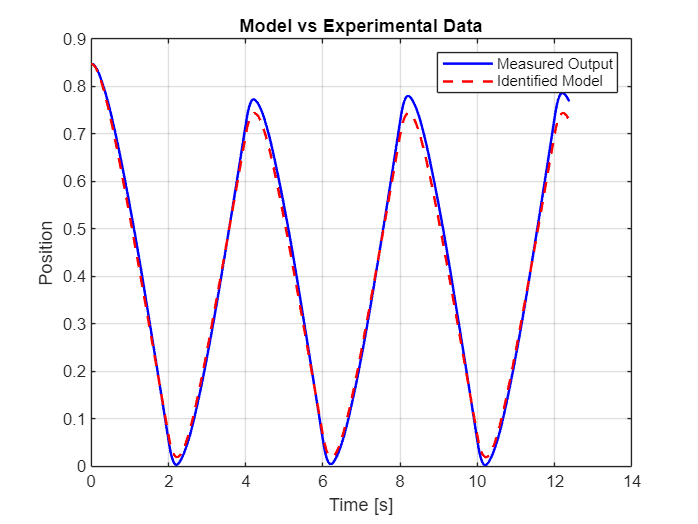


%% Build identified state-space model
A = [0 1;
     0 -a];
B = [0;
     b];
C = [1 0];
D = 0;

model = ss(A, B, C, D);

%% Simulate system response
x_init = [y(1) 0];              % Initial state
y_sim = lsim(model, u, t, x_init);

%% Compare measured and simulated output
figure;
plot(t, y, 'b', 'LineWidth', 1.5); hold on; grid on;
plot(t, y_sim, 'r--', 'LineWidth', 1.5);
legend('Measured Output', 'Identified Model');
xlabel('Time [s]');
ylabel('Position');
title('Model vs Experimental Data');
hold off;


%% ===== Cost Function =====
function J = costFunction(x, t, u, y)

    a = x(1);
    b = x(2);

    % State-space model
    A = [0 1;
         0 -a];
    B = [0;
         b];
    C = [1 0];
    D = 0;

    model = ss(A, B, C, D);

    % Simulate response
    x0 = [y(1) 0];
    y_sim = lsim(model, u, t, x0);

    % Mean squared error
    J = sum((y_sim - y).^2) / length(t);
end